# Digital Image Fundamentals

Created time : 2024/3/1 10:05

學號 : 109321019    姓名 : 涂价弘

# Lab-1

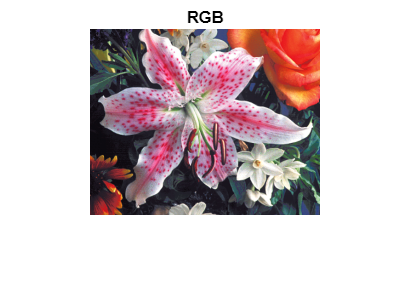

clf('reset');

img = imread('./images/2/lily.tif');

imshow(img)
title('RGB')

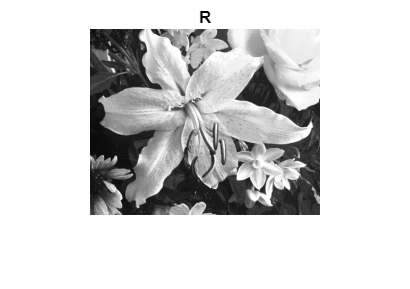


imshow(img(:, :, 1))
title('R')

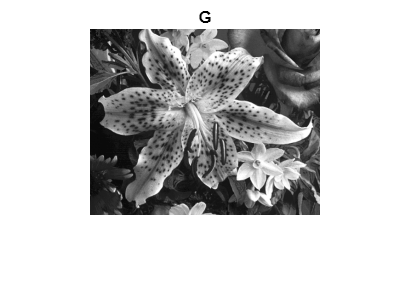


imshow(img(:, :, 2))
title('G')

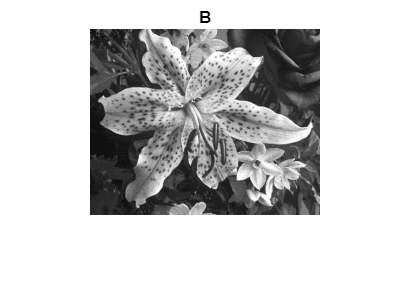


imshow(img(:, :, 3))
title('B')

# Lab-2

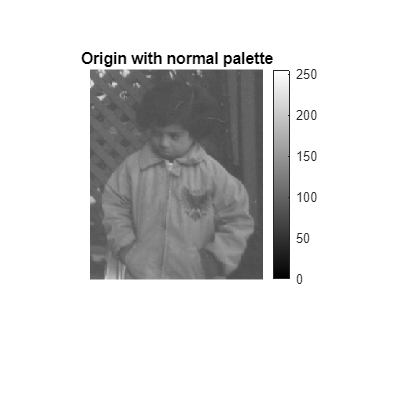

clf('reset');

img_uint_8 = imread('./images/2/pout.tif');
img_double = double(img_uint_8);

palette = [0 255];

imshow(img_uint_8, palette)
title('Origin with normal palette')
colorbar

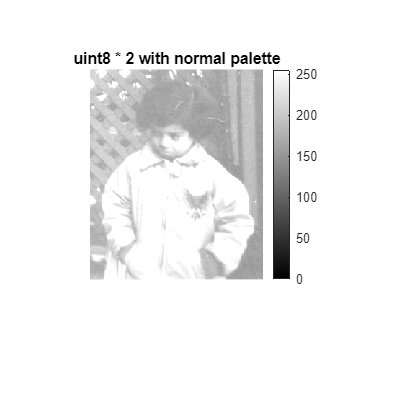


imshow(img_uint_8 * 2, palette)
title('uint8 * 2 with normal palette')
colorbar

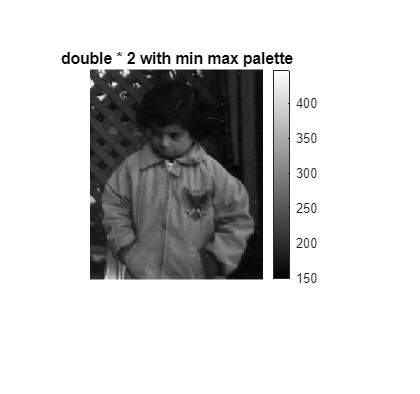


imshow(img_double * 2, [])
title('double * 2 with min max palette')
colorbar

# Lab-3

clf('reset');
addpath('./utils');

img = imread('./images/2/wombats.tif');
imwrite(img, './output/wombats.bmp', 'bmp');
imwrite(img, './output/wombats.jpg', 'jpg');

dumphex('./output/wombats.bmp', 2);
% width = height = 00 01 00 00

dumphex('./output/wombats.jpg', 1);
% JFIF version = 10 4A 46 49 46 00

# Lab-4

img = imread('./images/2/FigP1127(bubbles).tif');
imwrite(img, './output/bubbles_origin.jpg');
imwrite(img, './output/bubbles50.jpg', 'Quality', 50);
imwrite(img, './output/bubbles25.jpg', 'Quality', 25);
imwrite(img, './output/bubbles15.jpg', 'Quality', 15);
imwrite(img, './output/bubbles5.jpg', 'Quality', 5);
imwrite(img, './output/bubbles0.jpg', 'Quality', 0);

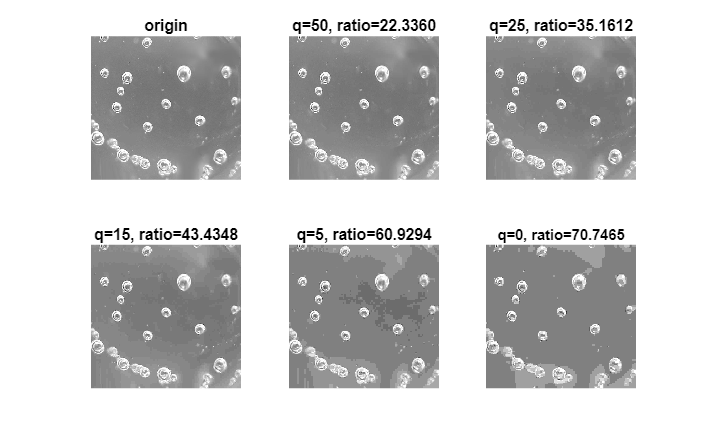

clf('reset');
addpath('./utils');

bubble_origin = imread('./output/bubbles_origin.jpg');
bubble50 = imread('./output/bubbles50.jpg');
bubble25 = imread('./output/bubbles25.jpg');
bubble15 = imread('./output/bubbles15.jpg');
bubble5 = imread('./output/bubbles5.jpg');
bubble0 = imread('./output/bubbles0.jpg');

subplot(2, 3, 1), imshow(bubble_origin);
title('origin')

ratio = get_img_ratio('./output/bubbles50.jpg');
subplot(2, 3, 2), imshow(bubble50)

title(sprintf('q=50, ratio=%0.4f', ratio))

ratio = get_img_ratio('./output/bubbles25.jpg');
subplot(2, 3, 3), imshow(bubble25);
title(sprintf('q=25, ratio=%0.4f', ratio))

ratio = get_img_ratio('./output/bubbles15.jpg');
subplot(2, 3, 4), imshow(bubble15);
title(sprintf('q=15, ratio=%0.4f', ratio))

ratio = get_img_ratio('./output/bubbles5.jpg');
subplot(2, 3, 5), imshow(bubble5);
title(sprintf('q=5, ratio=%0.4f', ratio))


ratio = get_img_ratio('./output/bubbles0.jpg');
subplot(2, 3, 6), imshow(bubble0);
title(sprintf('q=0, ratio=%0.4f', ratio))

truesize([200 200])